Controladores no EE

clear all

%constantes

m = 188.6 ; % Massa do ROV
I_z = 40.50 ; %Momento de inércia ao redor Z
m_u = 450.87; %Massa virtual na direção X
m_v = 558.92; %Massa virtual na direção Y
I_r = 239.44; %Momento virtual ao redor de Z

%coeficientes de arrasto hidrodinamico

K_u = 82.30;
K_uu = 309.70;
K_v = 8.50;
K_vv = 505.45;
K_r = 18.21;
K_rr = 94.72;

%velocidades iniciais

U = 0.5;
V = 0.5;
R = 0.126;

Matrizes

A = [ -(K_u/m_u)-((2*abs(U)*K_uu)/m_u), ((abs(R)*m_v)/m_u), ((abs(V)*m_v)/m_u);
    -((abs(R)*m_u)/m_v), -(K_v/m_v)-((2*abs(V)*K_vv)/m_v), -((abs(U)*m_u)/m_v);
    ((m_u-m_v)*abs(V)/I_r), ((m_u-m_v)*abs(U)/I_r), -(K_r/I_r)-((2*abs(R)*K_rr)/I_r)];

B = [1/m_u, 0, 0;
     0, 1/m_v, 0;
     0, 0, 1/I_r];

C = [1,0,0];

D = zeros(1,3);

E = [1/m_u; 1/m_v; 0];

B_novo = [B E];

D_novo = zeros(1,4);




Descretização e condições iniciais

t_ = 0:0.01:60;

x0 = [0;0;0];

u1_ = zeros(size(t_));

w = 10*sin(2*pi()*0.1*t_);

u2_ = zeros(size(t_));

u3_ = zeros(size(t_));

u_ = [u1_;u2_;u3_;w];


Por alocação de polos

polos = [-30,-20,-14];

Kaloc = place(A,B,polos);

Kaloc = 1.0e+04 *

    1.3134    0.0070    0.0279
   -0.0057    1.0664   -0.0225
   -0.0054   -0.0054    0.3310



Faloc = A-B*Kaloc; 

sysaloc = ss(Faloc,B_novo,C,D_novo); 

[h3_, t2, xal] = lsim(sysaloc, u_, t_, x0);

q1aloc = U + h3_(:,1);

q1_ = transpose(q1aloc);


Por malha aberta

sl = ss(A, B_novo, C, D_novo);

[y,x] = lsim(sl, u_, t_, x0);
y = transpose(y);

q1=  transpose(U + y(1,:)); 

Por LQR


Q = diag([50000,45000,40000]);

R_ = diag([0.002,0.0004,0.005]);

[K,P,E] = lqr(A,B,Q,R_);  

K = 1.0e+04 *

    0.4620    0.0016    0.0089
    0.0064    1.0107   -0.0239
    0.0067   -0.0045    0.2790


P = 1.0e+03 *

    4.1662    0.0143    0.0799
    0.0143    2.2597   -0.0534
    0.0799   -0.0534    3.3406


E =  -11.4747 + 0.2959i
 -11.4747 - 0.2959i
 -18.9996 + 0.0000i



F = A-B*K; 

sysF = ss(F,B_novo,C,D_novo); 

[h1_,t1,xlq] = lsim(sysF, u_, t_, x0); 

q1_lqr=  transpose(U + h1_(:,1)); 


força feita pelo atuador

ulq = -K*xlq';
ual = -Kaloc*xal';

Plots dos resultados

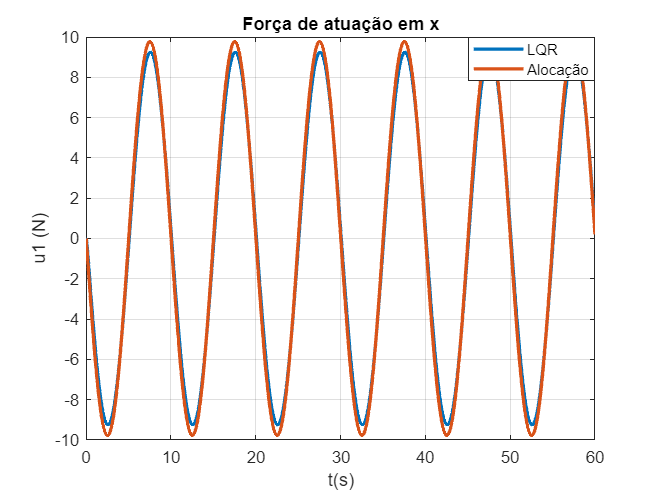

figure (1)
plot(t_, ulq(1,:),t_, ual(1,:), 'LineWidth', 2)
grid on 
legend('LQR', 'Alocação')
title('Força de atuação em x')
xlabel('t(s)')
ylabel('u1 (N)')

legend("Position", [0.71189,0.83714,0.19187,0.087298])

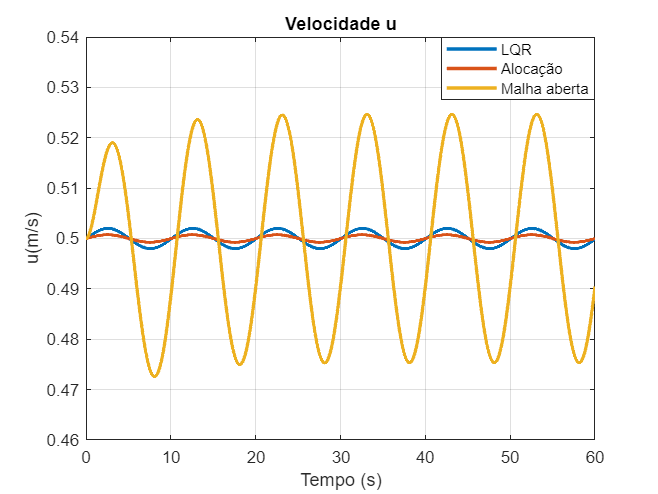




figure (2)
plot(t_, q1_lqr, t_, q1_, t_, q1, 'LineWidth', 2)
grid on
legend('LQR', 'Alocação', 'Malha aberta')
title('Velocidade u')
xlabel('Tempo (s)')
ylabel('u(m/s)')
ylim([0.46 0.54])

legend("Position", [0.672,0.79792,0.23176,0.12652])



p = pzmap(sysF);

p =  -11.4747 + 0.2959i
 -11.4747 - 0.2959i
 -18.9996 + 0.0000i
